# Homework 10

## Due Monday, April 11 before 5:00pm

*Use [Live Editor > Save > Export to PDF] to prepare your submission for Gradescope.*

## Cell/Matrix Interactions

Multivariable linear regression can be used to analyze large-scale datasets and to develop models that describe complex biological phenomena. The dataset that you will analyze in this problem is from an experiment designed to study how cancer cells interact with a set of proteins termed extracellular matrix (ECM) proteins.

ECM proteins (collagen is a very common example) provide structure to normal tissues as well as diseased tissues such as tumors. In addition to a structural role, ECM proteins can also provide important signals to cancer cells, which can help the cancer cells survive, proliferate, or migrate to other sites in the body. Although it is clear that ECM proteins are important in cancer, the overall matrix of a tumor consists of a complex combination of many different ECM proteins.  What is not currently known is, (i) what are the most important ECM proteins in different types of cancer, and (ii) what happens when cancer cells interact with combinations of ECM proteins at the same time?

For this problem, you will analyze actual data associated with the following experiment.  

- A lung cancer cell line was cultured on 55 different combinations of 10 ECM proteins (10 proteins listed in next bullet). These unique combinations included the 10 ECM proteins individually, and the 45 2-factor combinations of the 10 proteins. For example, one of the conditions was collagen 1 (C1) by itself, and then 9 other conditions were C1 paired with each of the other ECM proteins.

- ECM proteins (and abbreviations):  C1= collagen 1; C3= collagen 3; C4= collagen 4; G3= galectin-3; G8= galectin-8; OP= osteopontin; TC= tenascin-C; TR= tenascin-R; FN= fibronectin; LN= laminin

- After culture, the number of adherent cancer cells was quantified. If an ECM combination enhanced the number of adherent cells, then this ECM likely promotes cancer cell adhesion, survival, and possibly proliferation.

- For each ECM combination, there were approximately 15-20 replicate measurements of adherent cell number.

From this dataset, the goal is to quantitatively determine how individual ECM proteins, and specific combinations of ECM proteins, control lung cancer cell adhesion (adherent cell number).

Fit a linear model to predict the number of adherent cells for each ECM and their interactions. The data are stored in the variable `ecm`.

Notes (see `help fitlm` for more details):

- This experiment examined 10 distinct ECMs, not 10 variations on one “standard” ECM. As such, there should be no intercept in your model. You can disable the intercept with the ‘intercept’ argument.

- You can easily include interactions for all variables using the ‘interactions’ argument to fitlm.

- You can specify the response variable with the ‘ResponseVar’ argument.

load HW10_data.mat
rng(210); % set the random number generator

% place your code here

Every term in the linear model is nonzero (although only some a statistically significant). It's unlikely that all the combinations have a nonzero effect. The problem is our linear model includes a large number of features (1 intercept + 10 ECM proteins + 45 interactions) but lacks any regularization to enforce sparsity. Let's use the LASSO to fit a more parsimonious model.

## Preparing the Data

Matlab's `lasso` function does not use the formula-style input of `fitlm`. We need to construct our own model matrix with for all the proteins and their two-way interactions. The following code builds the model matrix. Stop here and try it for yourself first if you want a challenge!

First, let's pull the response vector out of the dataframe. It's in the column `ecm.cells`.

cells = ecm.cells;
ecm.cells = [];

The second line deletes the column from the data table. Now let's compute the size of the model matrix.

[n,k] = size(ecm);
p = 1 + k + nchoosek(k,2);

There are `n` rows (one per observation) and `k` proteins. The number of interactions is the number of ways we can choose two of the `k` proteins. The extra column of ones is for the intercept. Now we can create a model matrix and fill the corresponding columns.

X = ones(n,p);
X(:,2:k+1) = table2array(ecm); % Fill the first-order terms

% create a cell array of names for each term in the model
treatment = cell(p,1);
treatment{1} = '(Intercept)';
treatment(2:k+1) = ecm.Properties.VariableNames;

twi = 1+k+1; % current column
for i = 1:k
    for j = i+1:k
        X(:,twi) = X(:,1+i) .* X(:,1+j); % create the interaction
        treatment{twi} = [treatment{1+i} ':' treatment{1+j}]; % add the interaction name
        twi = twi + 1;
    end
end

Regularized Linear Regression with the LASSO

Now we're ready to use the `lasso` command to fit a linear model that penalizes nonzero coefficients.

[B,fitinfo] = lasso(X,cells,'NumLambda',10,'CV',5);

As we said in class, there isn't a good way to find the value of $\lambda$, the regularization constant. Instead we ask `lasso` to try a range of 10 different values using the `'NumLambda'` parameter. The `fitinfo` structure provides information about the model fitting.

fitinfo

fitinfo = struct with fields:
         Intercept: [10.0981 8.0219 6.5435 6.1946 5.6582 5.5577 6.0901 6.1985 6.7636 8.3640]
            Lambda: [2.6340e-04 7.3293e-04 0.0020 0.0057 0.0158 0.0439 0.1223 0.3402 0.9466 2.6340]
             Alpha: 1
                DF: [55 54 53 54 52 48 36 25 6 0]
               MSE: [54.3102 54.3094 54.2809 54.2044 54.0292 53.8536 54.2212 55.7172 61.1556 72.5458]
    PredictorNames: {}
                SE: [3.1073 3.1029 3.0949 3.0722 3.0304 2.8916 2.7921 3.0205 4.0866 5.5066]
      LambdaMinMSE: 0.0439
         Lambda1SE: 0.3402
       IndexMinMSE: 6
          Index1SE: 8


The `Lambda` field gives the 10 regularization constants tried by `lasso`. The `DF` field shows the number of degrees of freedom in the regularized models--this is the number of nonzero coefficients. Recall that our linear model used all 55 coefficients; the same is true for the model with the smallest regularization constant. As the regularization constant increases, the number of nonzero coefficients decreases.

Which regularization constant is best? We can turn to the `SE` field, which gives the standard error of the cross validation (5-fold cross validation, as we specified in our call to `lasso`). The smallest standard error occured with the 6th value in Lambda (given by `IndexMinMSE`), which is 0.0439 (`LambdaMinMSE` or `Lambda(6)`). This model would have 48 nonzero coefficents (`DF(6)`). However, our estimate of the model's accuracy contains some uncertainty. The `lasso` output also gives the standard error of the cross validation and tells us the largest value of `Lambda` that is within one standard error of the minimum (`Lambda1SE`). In many cases we would favor this value of `Lambda` (0.3402) over the true minimum (0.0439). Why?

*    Write your answer here.*

The matrix `B` returns the actual coefficients for each value of `Lambda`. Let's sort each model's coefficients by size and plot them to see the effects of regularization.

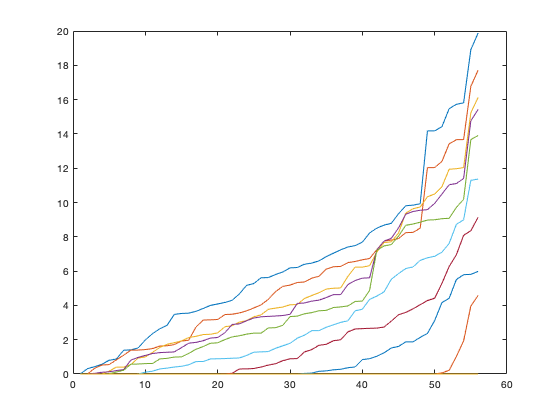

plot(sort(abs(B)))

Explain what you're seeing in this plot.

    *Write your answer here.*

Now we can identify the nonzero interactions from our regularized model. Let's put them in a table for display.

nonzeros = abs(B(:,8)) > 1e-5;
effect_size = B(nonzeros,8);
effect_name = treatment(nonzeros);
table(effect_name, effect_size)

ans = 25×2 table
    effect_name    effect_size
    ___________    ___________

      'C1'             5.7913 
      'C3'             1.8711 
      'C4'             4.4134 
      'G8'           0.052394 
      'OP'          -0.034028 
      'TC'            -1.8743 
      'TR'           -0.27539 
      'C1:OP'         0.36653 
      'C1:TR'          5.9844 
      'C1:LN'          1.5149 
      'C3:G8'         0.41212 
      'C3:OP'         -4.1638 
      'C3:FN'          1.2351 
      'C3:LN'          3.1175 
      'C4:G8'           5.511 
      'C4:OP'         0.89152 
